随机移动一个点，检查热阻，换热系数的变化

## 打开节点＆边文件

clc
clear



node_cor = load('F:\FEM\GraphAnalysis2\Optimiztion\symGraph\18_\nodes\df_Random_net_xy2112.txt');
bond_cor = load('F:\FEM\GraphAnalysis2\Optimiztion\symGraph\18_\edges\original_Network2112.txt');


% 调用函数路径
addpath('F:\FEM\GraphAnalysis2\Optimiztion\Function')


## 网络基本信息

bond = 12; % 边界坐标
n = 18; % 边界点数
bond_idx = n*4-4; % 边界最大点序号 
point_num = (n^2-bond_idx)/2;
total_points = n^2;
minpose = 0;
maxpose = 12;

## 计算初始值

Tem_Initial = CalculateTemperatureForOpt(bond_cor,node_cor,0,12);
[S_ini,A_ini] = FunCalculateVolAre(bond_cor,node_cor);
V_ini = G_A_CalculateVbybond(bond_cor, node_cor)

V_ini = 9.7914e+03

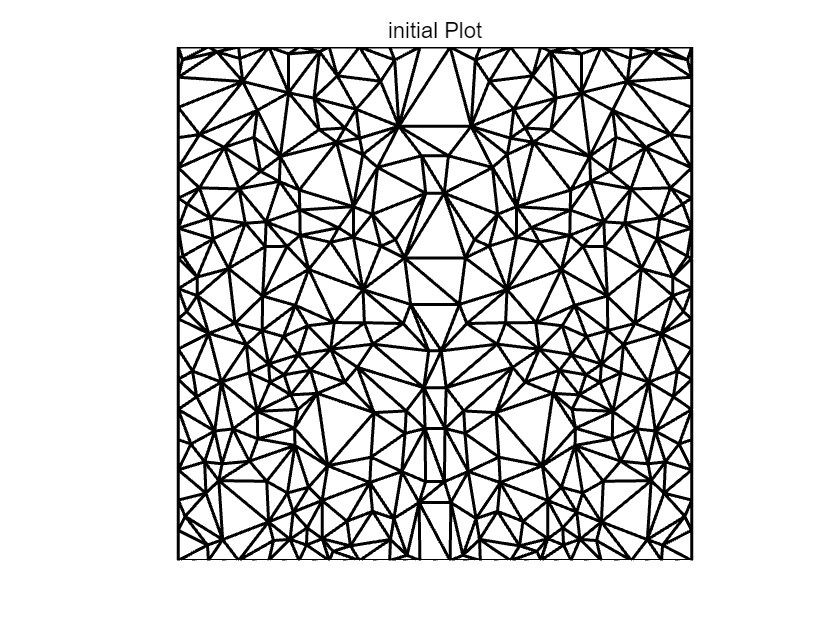

h_avgV_ini = 20/(Tem_Initial(1,2)*(V_ini*2*1e-9));
h_avgA_ini = 20/(Tem_Initial(1,2)*(A_ini*2*1e-9));
initial_Plot(bond_cor)

## 产生测试文件

node_cor_opt = node_cor;
[n_r,n_c] = size(node_cor_opt);

## 遗传算法基本信息

populationSize = 100 ; % 种群数量
L = point_num; % 染色体长度，此处为需要位移的点的坐标链长
generations = 10 ; %最大遗传代数
crossoverRate = 0.8;
mutationRate = 0.03;

% 生成信息 initialpopulation
start_nodeA = 69;
start_nodeB = 197;


## 预存

% 预存
fitness_V = zeros(populationSize,generations); % 用连接总面积计算总面积
fitness_SA = zeros(populationSize,generations); % 用图片计算面积

## 位移信息

%% 正负位移
Dis = 12/(18-1)/2;
GA_range = 100; %% 种群基因范围 
GA_step = Dis*2/GA_range; % 步长 

## 进入循环

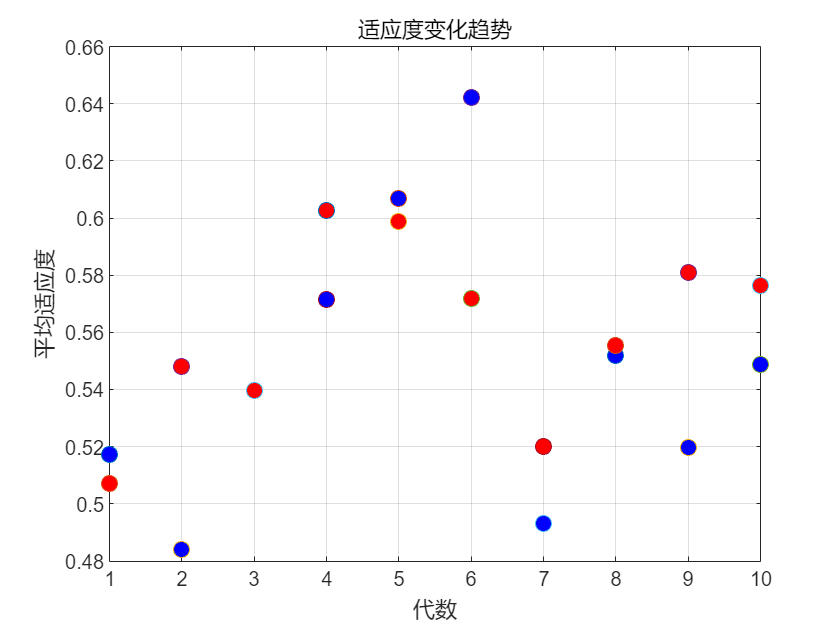

%%% 边界点最大序号 18*4-4 = 68 一共有128个点需要录入基因
%%% 对称图形
 
%  生成种群
population = G_A_initializePopulation(populationSize, GA_range, total_points,start_nodeA,start_nodeB);


% 循环代数
for generation = 1:generations
    
    population =  G_Acheck(population, maxpose, minpose, node_cor_opt, start_nodeA, start_nodeB, GA_step, bond);
    
    % 计算适应度
    [fitness_normalize, fitness_absolute] = G_A_CalculateFitness(node_cor_opt, population, GA_step, minpose, maxpose);

    % 筛选
    selectedPopulation = G_A_selection(population, fitness_normalize);
    
    % 交叉
    crossoveredPopulation = G_A_crossover(selectedPopulation, crossoverRate, start_nodeA, start_nodeB);
    
    % 变异
    mutatedPopulation = G_A_mutation(crossoveredPopulation, mutationRate, GA_range, start_nodeA,start_nodeB);
    
    % 更新种群
    population = mutatedPopulation;

    % 计算中间适应度
    intermediateFitness = mean(fitness_normalize,1);  % 这里可以选择其他方式计算中间适应度

    % 存储绝对适应度
    fitness_all_V(:,generation) = fitness_absolute(:,1);
    fitness_all_SA(:,generation) = fitness_absolute(:,2);

    % 绘制适应度点图
    plot(generation, intermediateFitness(:,1), 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    hold on;
    plot(generation, intermediateFitness(:,2), 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
end
% 设置图表属性
xlabel('代数');
ylabel('平均适应度');
title('适应度变化趋势');
grid on;
hold off;
hold off

## 画相对于基础结构的适应度变化曲线

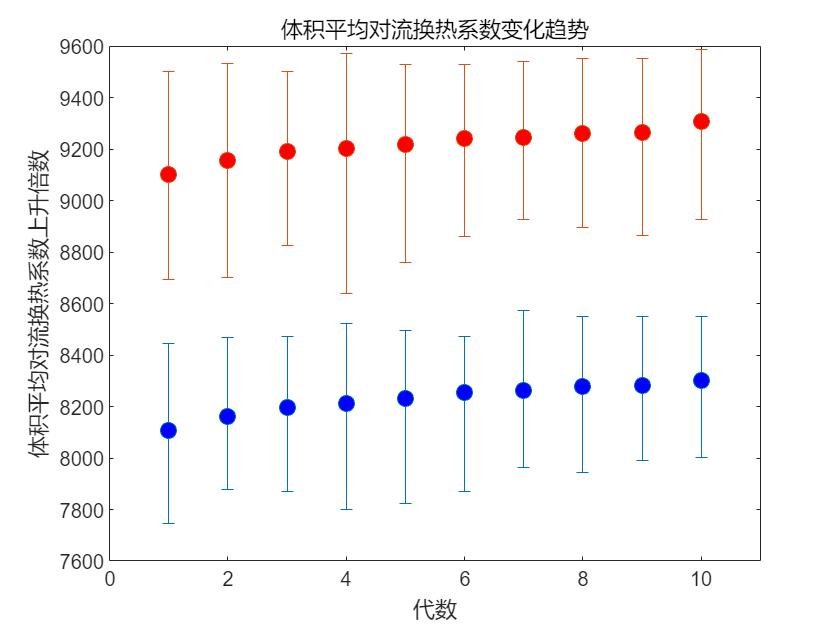

figure
fitness_all_nor_by_staV = fitness_all_V; % 用最基础结构的适应度进行约化
fitness_all_nor_by_staA = fitness_all_SA;% 用最基础结构的适应度进行约化

meanfitnessV = mean(fitness_all_nor_by_staV);  % 如果 A 为矩阵，那么 mean(A) 返回包含每列均值的行向量
maxfitnessV = max(fitness_all_nor_by_staV);
minfitnessV = min(fitness_all_nor_by_staV);
X = 1:generation; % 生成x
errorbar(X,meanfitnessV, meanfitnessV-minfitnessV, maxfitnessV-meanfitnessV, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on 

meanfitnessA = mean(fitness_all_nor_by_staA);  % 如果 A 为矩阵，那么 mean(A) 返回包含每列均值的行向量
maxfitnessA = max(fitness_all_nor_by_staA);
minfitnessA = min(fitness_all_nor_by_staA);

errorbar(X,meanfitnessA, meanfitnessA-minfitnessA, maxfitnessA-meanfitnessA, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlim([0 generation+1]);
ylabel('体积平均对流换热系数上升倍数');
title('体积平均对流换热系数变化趋势');
xlabel('代数');

## 检查

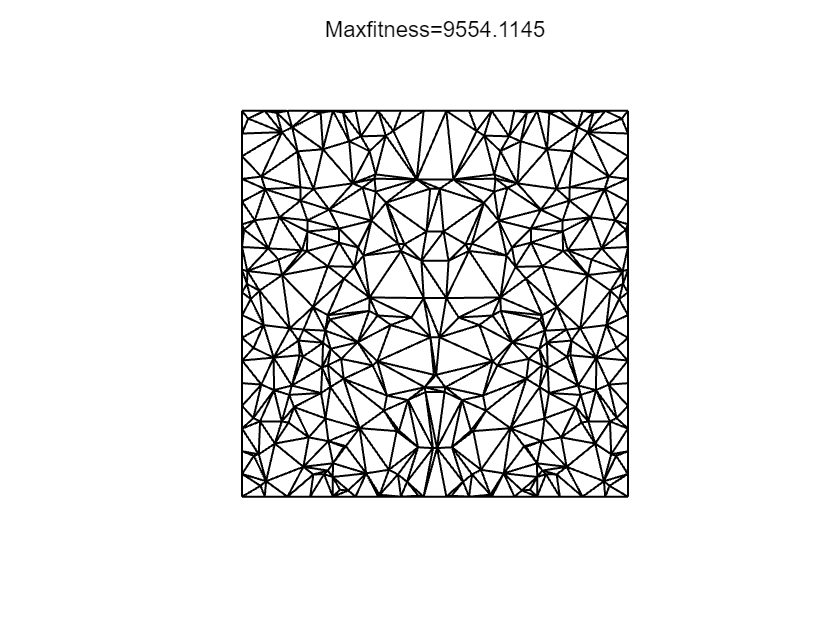

% 找到最大，最小适应度
idx_fitnessMaxA = find(fitness_all_nor_by_staA(:,end) == max(fitness_all_nor_by_staA(:,end)));
idx_fitnessMaxV = find(fitness_all_nor_by_staV(:,end) == max(fitness_all_nor_by_staV(:,end)));

% 画图 idx_fitnessMax(1,1)以防有多个
[node_corMAxA,bond_corMAxA ] = G_A_Postprocess(idx_fitnessMaxA(1,1),population,node_cor_opt,GA_step);
xlim([-2,14])
ylim([-2,14])
title(['Maxfitness=',num2str(fitness_all_nor_by_staA(idx_fitnessMaxV(1,1),end))]);

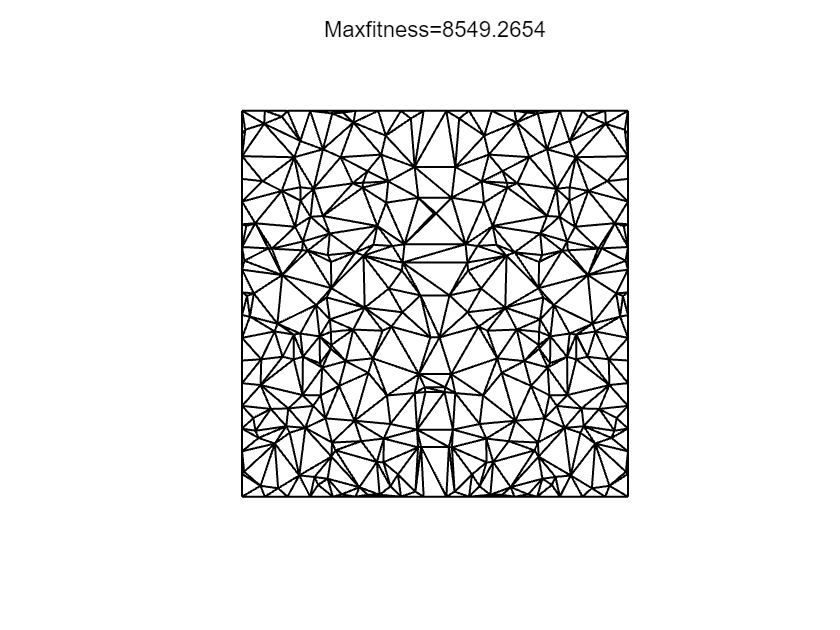


[node_corMaxV,bond_corMaxV ] = G_A_Postprocess(idx_fitnessMaxV(1,1),population,node_cor_opt,GA_step);
title(['Maxfitness=',num2str(fitness_all_nor_by_staV(idx_fitnessMaxV(1,1),end))]);
xlim([-2,14])
ylim([-2,14])

## 保存文件

 %save('2023_11_12_18_minh.mat')

## 导出坐标

 %writematrix(bond_corMAx,'18minhbondcorMax.txt',Delimiter=',');
 %writematrix(bond_corMin,'18minhbondcorMin.txt',Delimiter=',');